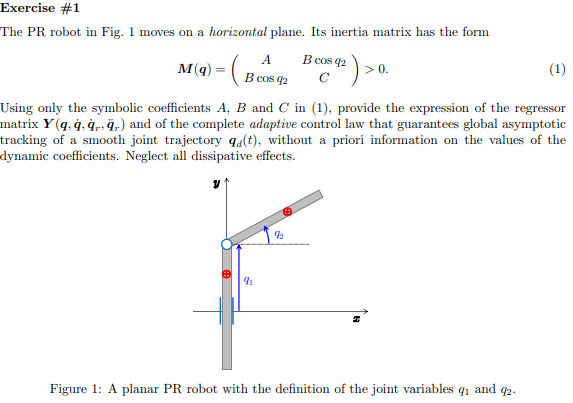

syms q1 q2 A B C q_dot_1r q_dot_2r q_ddot_1r q_ddot_2r real
syms L_1 L_2 L_3 L_4 q3 q4

M = [A B*cos(q2);
      B*cos(q2) C;];

% Coriolis and Centrifugal force
q  = [q1; q2;];
dqr = [q_dot_1r; q_dot_2r;];
dq = [q_dot_1; q_dot_2;];
ddq = [q_ddot_1r; q_ddot_2r;]; % Added acceleration terms
C_mat = sym(zeros(2,2)); % Renamed to avoid conflict with C parameter

for i = 1:2
    for j = 1:2
        tmp = 0;
        for k = 1:2
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C_mat(i,j) = simplify(tmp);
    end
end

c_vec = simplify(C_mat * dqr)

$$c\_vec = \left(\begin{array}{c} -B\,{\dot{q}}_{2}\,{\dot{q}}_{\mathrm{2r}}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$


% Correct dynamic model: M*ddq + C*dq
dynamicModel = M * ddq + c_vec; % Now a 2x1 vector

params = [A B C];
Y = extract_Y_v3(dynamicModel, params)

$$Y = \left(\begin{array}{ccc} {\ddot{q}}_{\mathrm{1r}} & {\ddot{q}}_{\mathrm{2r}}\,\cos\left(q_{2}\right)-{\dot{q}}_{2}\,{\dot{q}}_{\mathrm{2r}}\,\sin\left(q_{2}\right) & 0\\ 0 & {\ddot{q}}_{\mathrm{1r}}\,\cos\left(q_{2}\right) & {\ddot{q}}_{\mathrm{2r}} \end{array}\right)$$

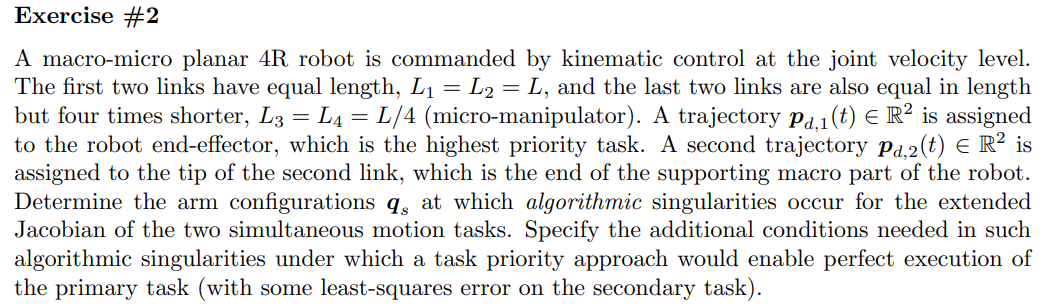

syms L q1 q2 q3 q4 
P_M = [L*cos(q1)+L*cos(q1+q2); L*sin(q1)+L*sin(q1+q2);]

$$P\_M = \left(\begin{array}{c} L\,\cos\left(q_{1}+q_{2}\right)+L\,\cos\left(q_{1}\right)\\ L\,\sin\left(q_{1}+q_{2}\right)+L\,\sin\left(q_{1}\right) \end{array}\right)$$

P_m = [L*cos(q1+q2+q3)+L*cos(q1+q2+q3+q4); L*sin(q1+q2+q3)+L*sin(q1+q2+q3+q4);]

$$P\_m = \left(\begin{array}{c} L\,\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right)+L\,\cos\left(q_{1}+q_{2}+q_{3}\right)\\ L\,\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)+L\,\sin\left(q_{1}+q_{2}+q_{3}\right) \end{array}\right)$$


J_M = jacobian(P_M,[q1,q2,q3,q4])

$$J\_M = \left(\begin{array}{cccc} -L\,\sin\left(q_{1}+q_{2}\right)-L\,\sin\left(q_{1}\right) & -L\,\sin\left(q_{1}+q_{2}\right) & 0 & 0\\ L\,\cos\left(q_{1}+q_{2}\right)+L\,\cos\left(q_{1}\right) & L\,\cos\left(q_{1}+q_{2}\right) & 0 & 0 \end{array}\right)$$

J_m = jacobian(P_m,[q1,q2,q3,q4])

$$J\_m = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & \sigma_{2} & \sigma_{2} & -L\,\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)\\ \sigma_{1} & \sigma_{1} & \sigma_{1} & L\,\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L\,\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right)+L\,\cos\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{2}=-L\,\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)-L\,\sin\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$


J_e = [J_m; J_M;]

$$J\_e = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & \sigma_{2} & \sigma_{2} & -L\,\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)\\ \sigma_{1} & \sigma_{1} & \sigma_{1} & L\,\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right)\\ -L\,\sin\left(q_{1}+q_{2}\right)-L\,\sin\left(q_{1}\right) & -L\,\sin\left(q_{1}+q_{2}\right) & 0 & 0\\ L\,\cos\left(q_{1}+q_{2}\right)+L\,\cos\left(q_{1}\right) & L\,\cos\left(q_{1}+q_{2}\right) & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L\,\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right)+L\,\cos\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{2}=-L\,\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)-L\,\sin\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

det_Je = simplify(det(J_e))

$$det\_Je = L^{4}\,\sin\left(q_{2}\right)\,\sin\left(q_{4}\right)$$


J_e_subs = subs(J_e,[q2],[0])

$$J\_e\_subs = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & \sigma_{1} & \sigma_{1} & -L\,\sin\left(q_{1}+q_{3}+q_{4}\right)\\ \sigma_{2} & \sigma_{2} & \sigma_{2} & L\,\cos\left(q_{1}+q_{3}+q_{4}\right)\\ -2\,L\,\sin\left(q_{1}\right) & -L\,\sin\left(q_{1}\right) & 0 & 0\\ 2\,L\,\cos\left(q_{1}\right) & L\,\cos\left(q_{1}\right) & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-L\,\sin\left(q_{1}+q_{3}\right)-L\,\sin\left(q_{1}+q_{3}+q_{4}\right)\\ \sigma_{2}=L\,\cos\left(q_{1}+q_{3}\right)+L\,\cos\left(q_{1}+q_{3}+q_{4}\right) \end{array}$$

J_M_subs = subs(J_M,[q2],[0])

$$J\_M\_subs = \left(\begin{array}{cccc} -2\,L\,\sin\left(q_{1}\right) & -L\,\sin\left(q_{1}\right) & 0 & 0\\ 2\,L\,\cos\left(q_{1}\right) & L\,\cos\left(q_{1}\right) & 0 & 0 \end{array}\right)$$

J_m_subs = subs(J_m,[q2],[0])

$$J\_m\_subs = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & \sigma_{1} & \sigma_{1} & -L\,\sin\left(q_{1}+q_{3}+q_{4}\right)\\ \sigma_{2} & \sigma_{2} & \sigma_{2} & L\,\cos\left(q_{1}+q_{3}+q_{4}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-L\,\sin\left(q_{1}+q_{3}\right)-L\,\sin\left(q_{1}+q_{3}+q_{4}\right)\\ \sigma_{2}=L\,\cos\left(q_{1}+q_{3}\right)+L\,\cos\left(q_{1}+q_{3}+q_{4}\right) \end{array}$$

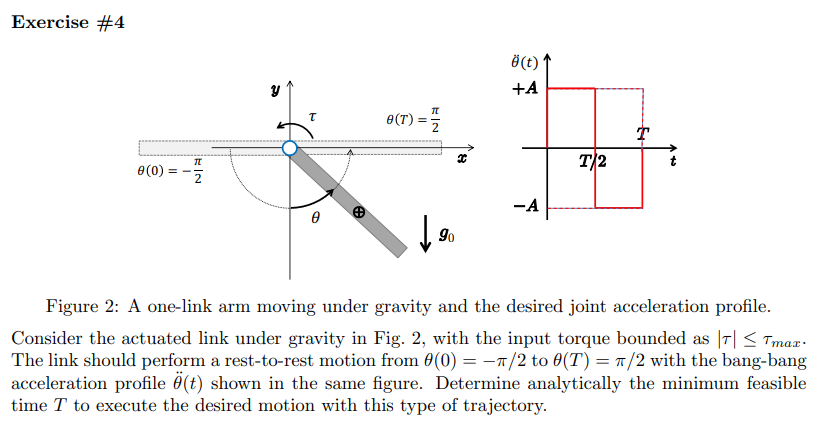

### Utils function

% Ensure the helper function is correctly handling vector inputs
function Y = extract_Y_v3(Ya, dynamic_symbols)
    Y = sym([]);
    Y_columns = length(dynamic_symbols);
    dynamic_symbols = reshape(dynamic_symbols, 1, Y_columns);

    for i=1:Y_columns
        subs_array = zeros(1, Y_columns);
        subs_array(i) = 1;
        Yi = subs(Ya, dynamic_symbols, subs_array);
        Y = [Y, Yi];
    end
end